# Loading the ECG file  

fnam = '/Users/zzr/Desktop/bme4101/4101lab2/ECG2/CoolTerm Capture 2023-03-16 21-57-09.asc'		% name of the data , this could be ECG3.dat, ECG4.dat, or ECG5.dat %%%%%Problem-1

fnam = '/Users/zzr/Desktop/bme4101/4101lab2/ECG2/CoolTerm Capture 2023-03-16 21-57-09.asc'

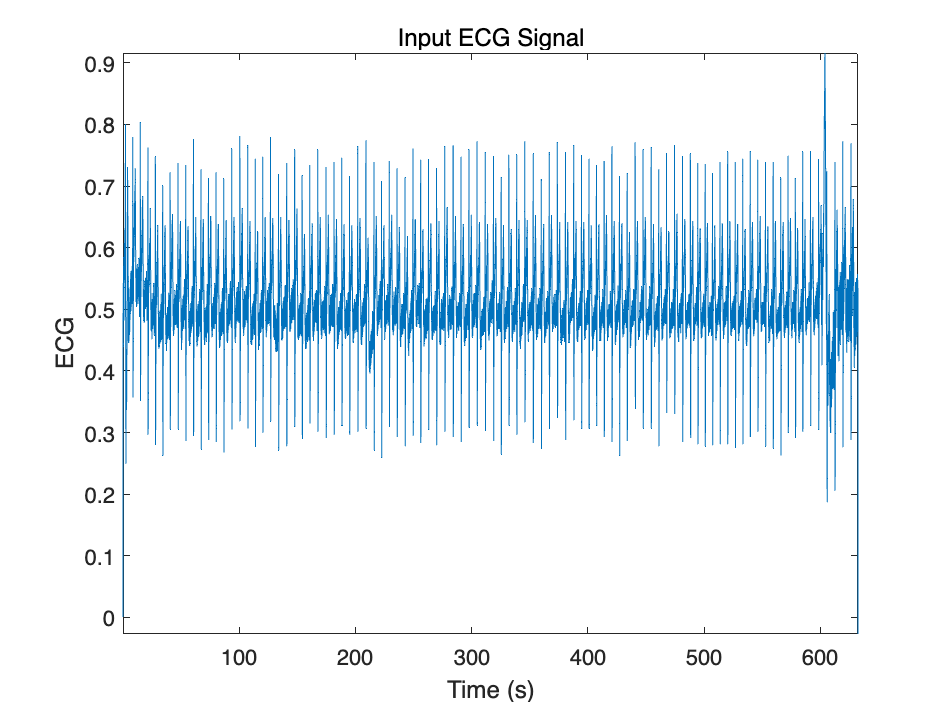

fid = fopen(fnam); 
ecg = fscanf(fid,'%f ');
fs = 200; 				% sampling rate, 200 Hz
sze = length(ecg);
necg = ecg/max(ecg); %	 normalize the maximum value to unity
time = [1 : sze]/fs;
% subtracting the first value
necg = necg-necg(1);

figure(1)
plot(time,necg);
axis tight;
ylabel('ECG');
xlabel('Time (s)');title('Input ECG Signal'); % Plot the Input ECG Signal

%conputing signal-to-noise ration
%SNR=snr(necg,fs)

data=EMG.("")
c=data(7999:10000);
Nr=normalize(c,'range');
Nr=detrend(Nr);

y=fft(Nr);
fs=2000;
f=(0:length(y)-1)*fs/length(y);


## Your code begins after this point.

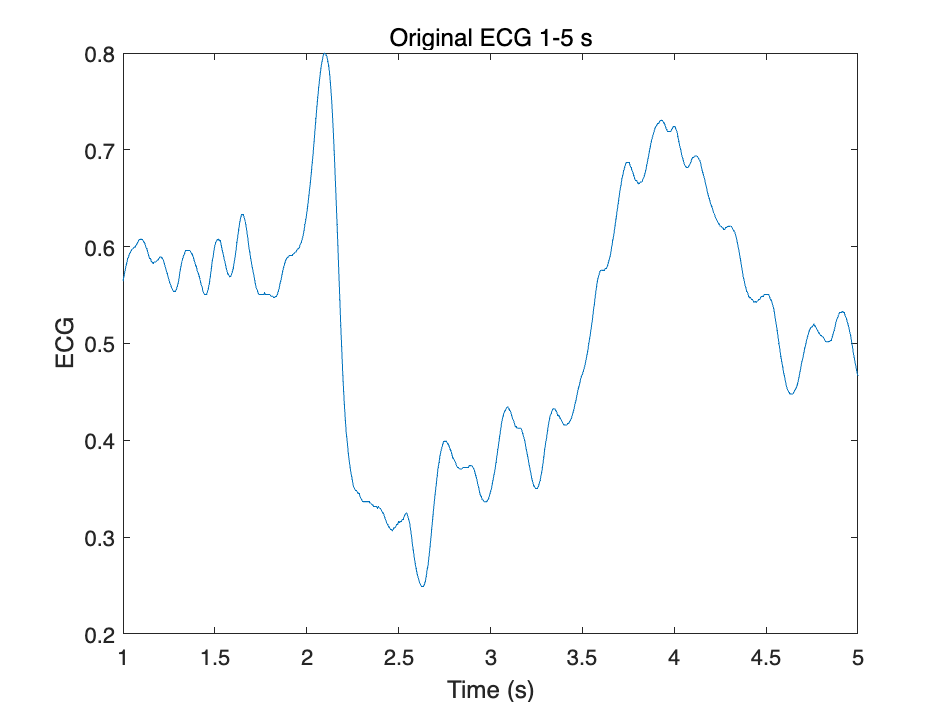


% For easier observation, we plot the signal within 1-5 seconds:
figure(2)
plot(time(200:1000),necg(200:1000));
xlabel('Time (s)');ylabel('ECG');title('Original ECG 1-5 s');
xlim([1 5]);

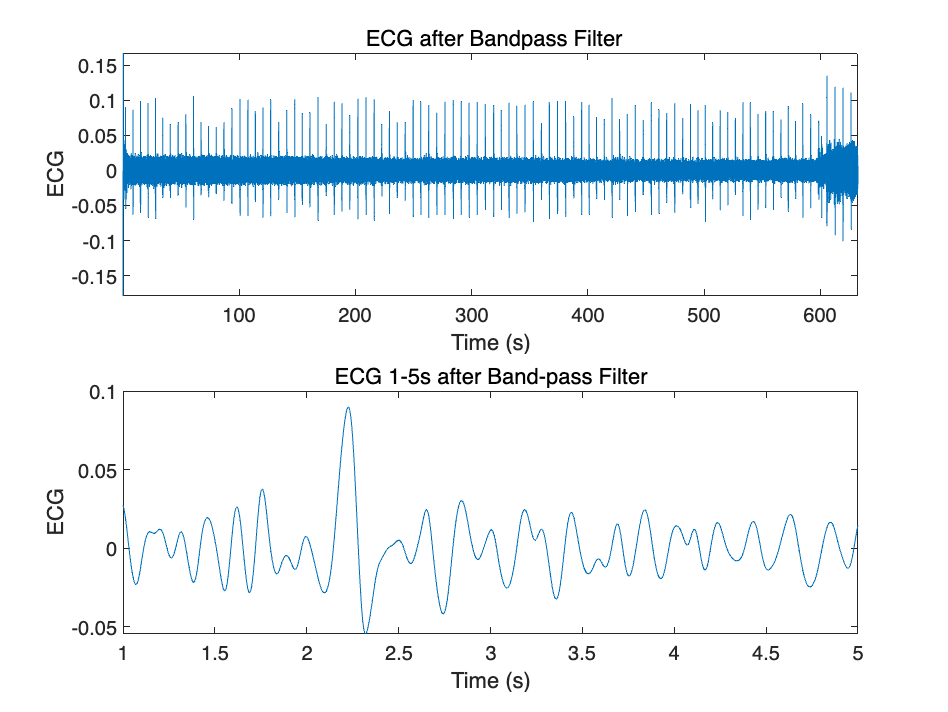


% First, we apply the band pass filter to the signal, the following is the
% low pass filter:

fs = 200; % discrete −time signal sampling
z = tf('z',1/fs); % creates a ’z’ object

Hlp = (1/32)*(1-z^-6)^2/(1-z^-1)^2; % desired transfer function for the low pass filter.
y1 = lsim(Hlp,necg) ; % apply the transfer function ( in the frequency domain) to signal in the time domain.
% y1 is the signal after low-pass filter

% Then, we shall apply the high pass filter to the signal

Hhp = z^-16 - (1/32)*(1-z^-32)/(1-z^-1); % desired transfer function .
y2 = lsim(Hhp,y1) ; % apply the transfer function ( in the frequency domain) to signal in the time domain
%y2 is the signal after the ban-pass filter

% Plot the signal after bandpass filter:
figure(3)
subplot(2,1,1)
plot(time,y2);
axis tight;
ylabel('ECG');
xlabel('Time (s)');title(' ECG after Bandpass Filter');
% For easier observation, we plot the signal after Bandpass filter within 1-5 seconds:
subplot(2,1,2)
plot(time(200:1000),y2(200:1000));
xlabel('Time (s)');ylabel('ECG');title('ECG 1-5s after Band-pass Filter')
xlim([1 5])

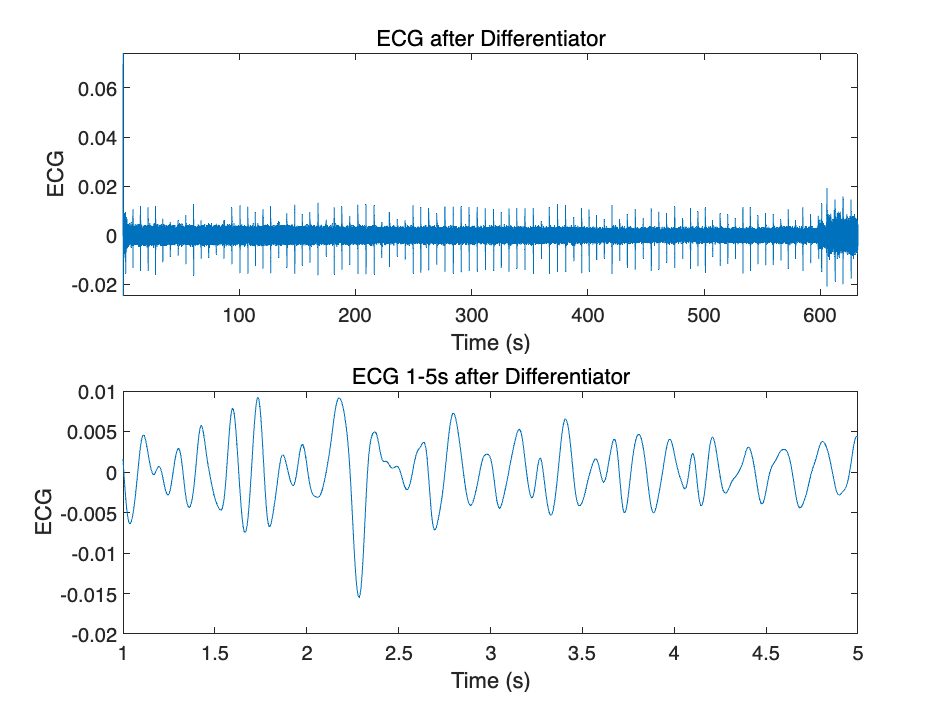



%To remain the size of the orignal signal during derivation, we need to append some '0' 
%values to the beginning and ending of the signal

%Apply the derivative filter
Hdo=(1/8)*(2+z^-1-z^-3-2*z^-4);
y3=lsim(Hdo,y2);
%y3 is the signal after derivative filter

% Plot the signal after derivative filter:
figure(4)
subplot(2,1,1)
plot(time,y3);
axis tight;
ylabel('ECG');title('ECG after Differentiator');
xlabel('Time (s)');
% For easier observation, we plot the signal after derivative filter within 1-5 seconds:
subplot(2,1,2)
plot(time(200:1000),y3(200:1000));
xlabel('Time (s)');ylabel('ECG');title('ECG 1-5s after Differentiator')
xlim([1 5])

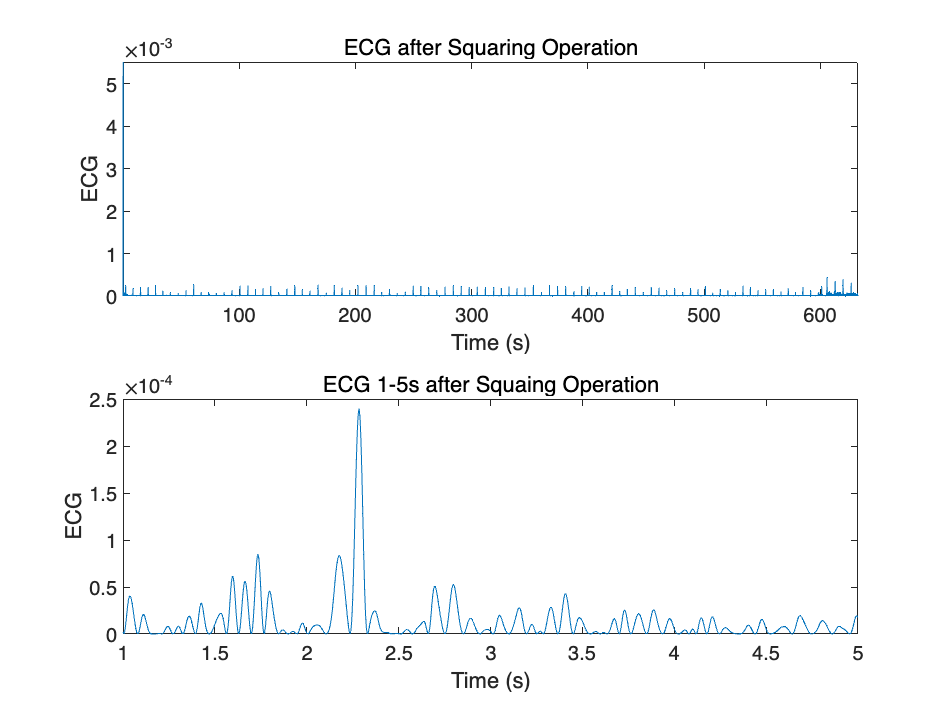



% Then, we shall apply the squaring filter to the signal
for n=1:length(y3)
    y4(n)=y3(n)^2;
end
%y4 is the signal after squaring operation

% Plot the signal after squaring operation:
figure(5)
subplot(2,1,1)
plot(time,y4);
axis tight;
ylabel('ECG');
xlabel('Time (s)');title('ECG after Squaring Operation');
% For easier observation, we plot the signal after squaring operation within 1-5 seconds:
subplot(2,1,2)
plot(time(200:1000),y4(200:1000));
xlabel('Time (s)');ylabel('ECG');title('ECG 1-5s after Squaing Operation')
xlim([1 5])

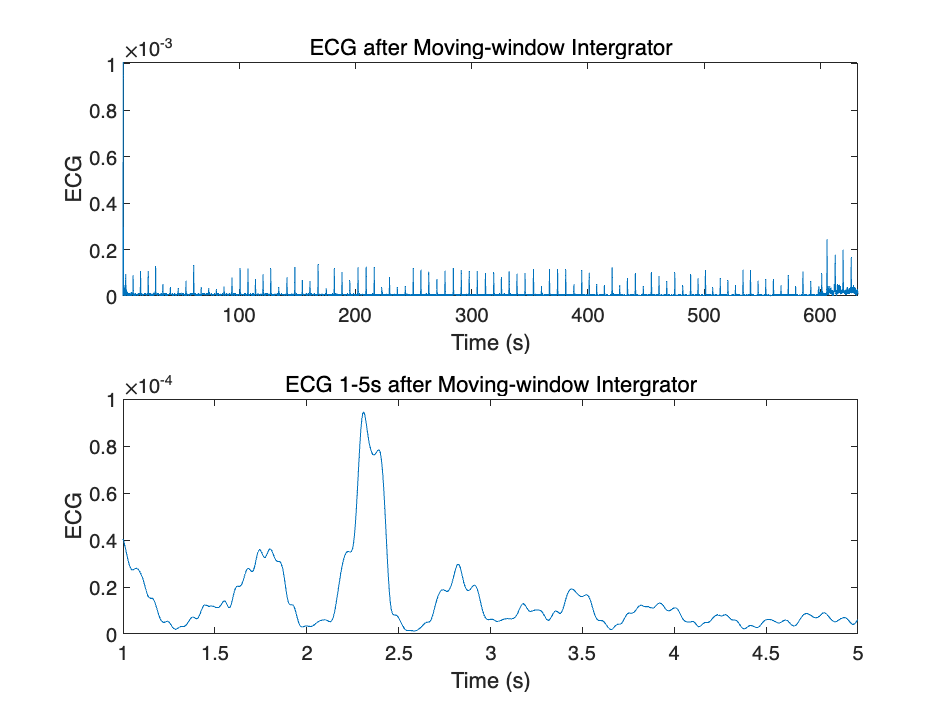


%To remain the size of the signal during moving window intergration, we need to append some '0' 
%values to the beginning and ending of the signal
listb=zeros(1,29);
yb=[listb y4 listb];
l2=30:1:length(y4)+29;

% Then we apply the moving window intergration 
for t=l2
    listc=yb(t-29:t);
    y5(t-29)=sum(listc)/30;
end
%y5 is the signal after Moving Window Intergration

% Plot the signal afer moving window intergration:
figure(6)
subplot(2,1,1)
plot(time,y5);
axis tight;
ylabel('ECG');title('ECG after Moving-window Intergrator');
xlabel('Time (s)');
% For easier observation, we plot the signal after intergration within 1-5 seconds:
subplot(2,1,2)
plot(time(200:1000),y5(200:1000));
xlabel('Time (s)');ylabel('ECG');title('ECG 1-5s after Moving-window Intergrator')
xlim([1 5])

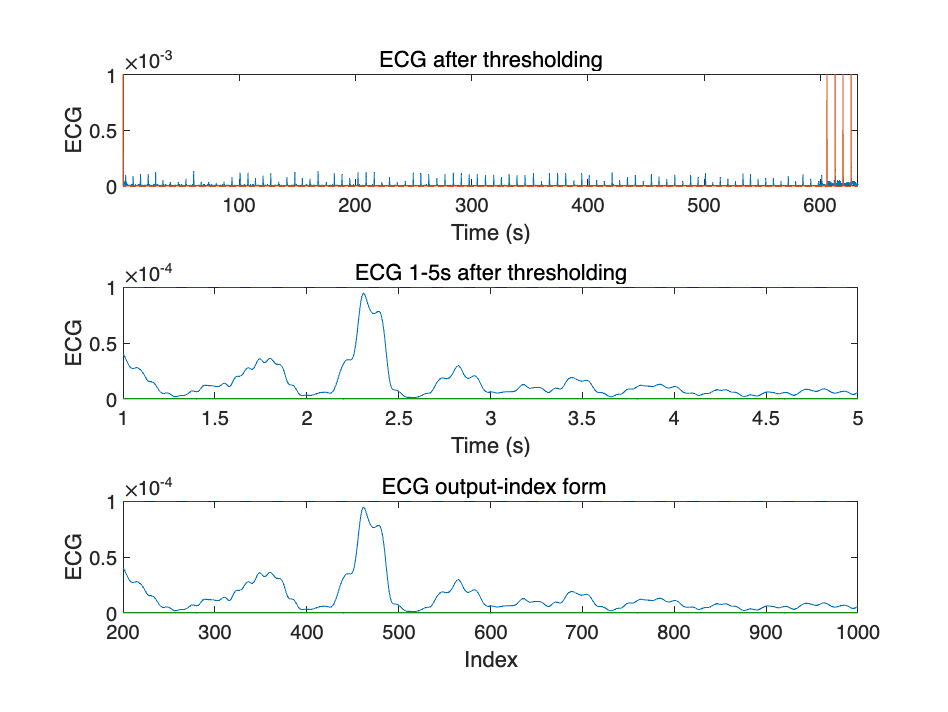



% Finally, we can use the pan_tompkins_thresholding_fn function to obtain 
% the QRS width

threshold=0.0001; % We choose the threshold to be 0.0001
% Applying the pan_tompkins_thresholding_fn function:
[square_output, index_i, index_f] = pan_tompkins_thresholding_fn(y5,threshold, 30);

% Then, we plot the ECG after thresholding function:
figure(7)
subplot(3,1,1)
plot(time,y5,time,square_output);
axis tight;
ylabel('ECG');title('ECG after thresholding');
xlabel('Time (s)');
% For easier observation, we plot the signal after thresholding within 1-5 seconds:
subplot(3,1,2)
plot(time(200:1000),y5(200:1000),time(200:1000),square_output(200:1000),'g');
xlabel('Time (s)');ylabel('ECG');title('ECG 1-5s after thresholding')
hold on
yline(threshold,'r--')
hold off
xlim([1 5])
% Also, we plot the ECG in scale of index (200-1000, corresponding to 1-5s):
ind=200:1000;
subplot(3,1,3)
plot(ind,y5(200:1000),ind,square_output(200:1000),'g');
xlabel('Index');ylabel('ECG');title(' ECG output-index form')
hold on
yline(threshold,'r--')
sz=25;
scatter(index_i((200<index_i)&(index_i<1000)),y5(index_i((200<index_i)&(index_i<1000))),sz)
scatter(index_f((200<index_f)&(index_f<1000)),y5(index_f((200<index_f)&(index_f<1000))),sz)
hold off


% If the number of starting points equals to the number of ending points of
% the trapezoid, there is a completed cycle:

if length(index_i)== length(index_f)
    beats=length(index_f);
else
    beats=length(index_i);
end

%Afterwards, we calculate the QRS Width using the output of the
%thresholding function:
ind_width=zeros(1,length(index_i)); % Calculate the width of the trapezoid
for k=1:length(index_i)
    ind_width(k)=index_f(k)-index_i(k);

end
ind_width=ind_width/200; % Turn the unit to s
ind_width=ind_width-30/200; % QRS Width = width of the trapezoid - W, and W=30/200;
ind_width=ind_width*1000; % Unit converting (ms)
ind_width_mean=mean(ind_width); % Calculate the mean QRS Width (Unit: ms)


%Then, we calculate average RR Interval using the peaks in each trapezoid:
max_RR=zeros(1,length(index_i)); % To pick the peaks in each trapezoid
for t=1:length(index_i)
    [row,col]=find(y5==max(y5(index_i(t):index_f(t))));
    for i=col
        if (index_i(t)<i)&&(i<index_f(t))
            max_RR(t)=i;
        end
    end

end
% Calculate the length of RR interval: 
RR_len=zeros(1,length(max_RR)-1);
max_RR=max_RR/200;
for i =1:length(max_RR)-1
    RR_len(i)=max_RR(i+1)-max_RR(i);
end

RR_len=RR_len*1000; % Convert unit to ms
% Mean of RR interval (Unit: ms);
average_len=mean(RR_len);
% Standard Deviation of RR intervals (in ms):
RRintervals_std = std(RR_len);



% Display results:

disp(['Total number of beats detected in each signal:',num2str(beats)]);

Total number of beats detected in each signal:5


disp(['Heart rate in beats per minute (Calculated by RR interval):',num2str(60/(average_len/1000))]); % In minute

Heart rate in beats per minute (Calculated by RR interval):0.38314


disp(['Average RR interval (in ms):',num2str(average_len)]);

Average RR interval (in ms):156602.5


disp(['Standard Deviation of RR intervals (in ms):',num2str(RRintervals_std)]);

Standard Deviation of RR intervals (in ms):299371.6801


disp(['Average QRS width (in ms):',num2str(ind_width_mean)]);

Average QRS width (in ms):55



% SNR=snr(y5,fs)

function [yout, n_i, n_f] = pan_tompkins_thresholding_fn(x_in,threshold, min_len)
	% x_in, input signal after the movinvg average step of the P-T algorithm.
	% threshold, the estimated magnitude of the input above the noise level.
	% yout, the output signal (same size as x_in) that is an envelope of the QRS complex (for visualization).
	% n_i, a vector of time indices corresponding to the beginning of the trapezoid.
	% n_f, a vector of time indices corresponding to the end of the trapezoid

	n_i = [];
	n_f = [];
	yout = zeros(length(x_in),1);
	i = 1;
	while i<(length(x_in)-1)
		if and(x_in(i+1)>threshold, x_in(i)<threshold)
			j = i;
			while and(x_in(i+1) > threshold,i<(length(x_in)-1))
				i = i+1;
			end
			k = i+1;
			if k-j > min_len
				n_i = [n_i j];
				n_f = [n_f k];
				yout(j:k) = 1*max(x_in);
			end
		end
		i = i+1;		

	end
end
